# Pole Placement Control: Performances

## System Data

clear 
close all
close all

% data for simscape model
% Run this block to initialise simscape pendulum model parameters

% Initial pendulum intial angle in degrees
% 180 corresponds to upright position
% can also be selected in the simulink model
alpha_0=170;

parametri = 1;      % 0 = nominali; 1 = identificati

%% System parameters
if parametri == 0
    B_p = 0.0024; % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = 0.0024; % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = 0.0020; % Rotary arm moment of inertia about pivot m^2
    J_p = 0.0012; % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = 0.156;  % Distance from pivot to center of mass m
    m_p = 0.127;  % Mass of pendulum Kg
    r = 0.216;    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = 9.81;     % gravitational acceleration m/s^2

    K_g = 70;      % High-gear total gear ratio
    R_m = 2.6;     % Ohm
    eta_g = 0.90;  % Gearbox efficiency
    eta_m = 0.69;  % Motor efficiency
    k_m = 7.68e-3; % Motor back-emf constant V/(rad/s)
    k_t = 7.68e-3; % Motor current-torque constant N*m/A

    L_p = 0.337; % total length of the vertical pendulum, needed for disturbance modeling
else
    % Valori identificati
    load("th_id.mat")
    B_p = id_param(1); % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = id_param(2); % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = id_param(3); % Rotary arm moment of inertia about pivot m^2
    J_p = id_param(4); % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = id_param(5);  % Distance from pivot to center of mass m
    m_p = id_param(6);  % Mass of pendulum Kg
    r = id_param(7);    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = id_param(8);     % gravitational acceleration m/s^2

    K_g = id_param(9);      % High-gear total gear ratio
    R_m = id_param(10);     % Ohm
    eta_g = id_param(11);  % Gearbox efficiency
    eta_m = id_param(12);  % Motor efficiency
    k_m = id_param(13); % Motor back-emf constant V/(rad/s)
    k_t = id_param(14); % Motor current-torque constant N*m/A

    L_p = 0.337; % total length of the vertical pendulum, needed for disturbance modeling
end

voltage_max = 10;
theta_max = 45;     % Maximum theta rotation[deg]
alpha_max = 15;     % Maximum alpha deflection [deg]

## System State Space representation around the unstable equilibrium

% [A,B,C,D] = SS_Matrices_Voltage_Unstable(B_p,B_r,J_T,J_a,J_p,K_g,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
% 
% C_full = eye(4); % we assume to measure the full state of the system
% D_full = zeros(4,1);

[A,B,C,D] = SS_Matrices_Voltage_Unstable_Disturbance(B_p,B_r,J_T,J_a,J_p,K_g,L_p,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
B_d = B(:,2); % disturbance matrix
B_u = B(:,1); % input matrix
C_full = eye(4);
D_full = zeros(4,size(B,2));
D_full_u = D_full(:,1);

**Remark: **In simulation, always use the system with full state!!! In this way you can see also the simulation of the states that in the real setup are not measurable.

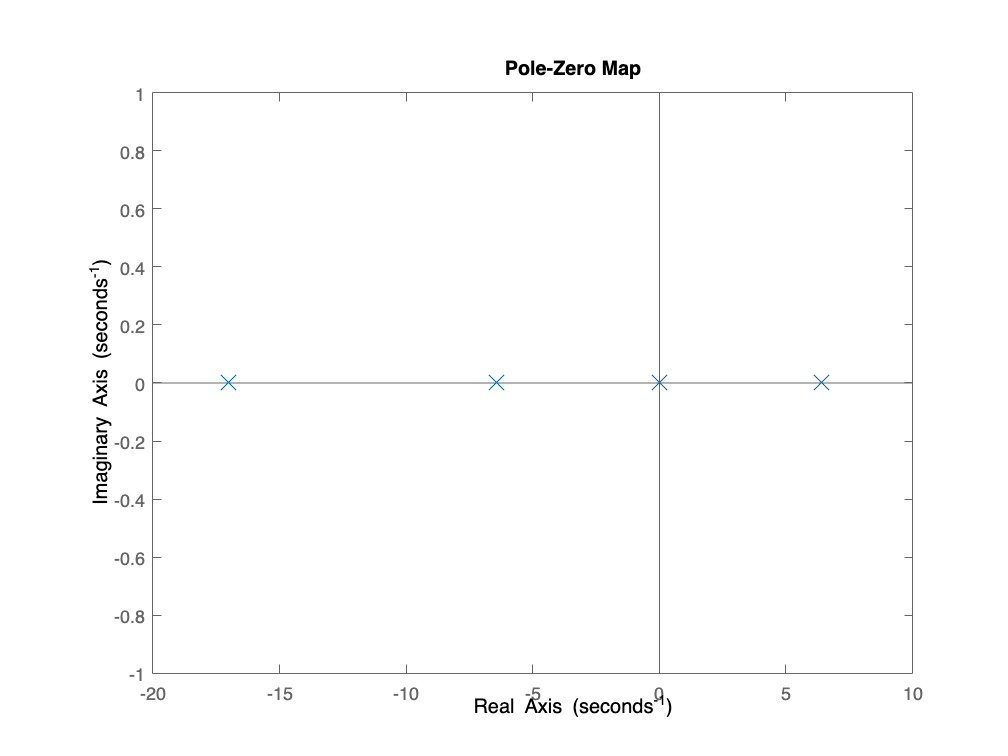

sys_ol = ss(A,B_u,C_full,D_full_u); % open loop system

figure(1);
pzmap(sys_ol)
set(findobj(gca, 'type', 'line'), 'MarkerSize', 12);

We can see the presence of:

- An unstable real pole

- A zero at the origin

poli = pole(sys_ol)

poli =          0
    6.4075
   -6.4233
  -17.0228


zeri = tzero(sys_ol)


zeri =

  0×1 empty double column vector



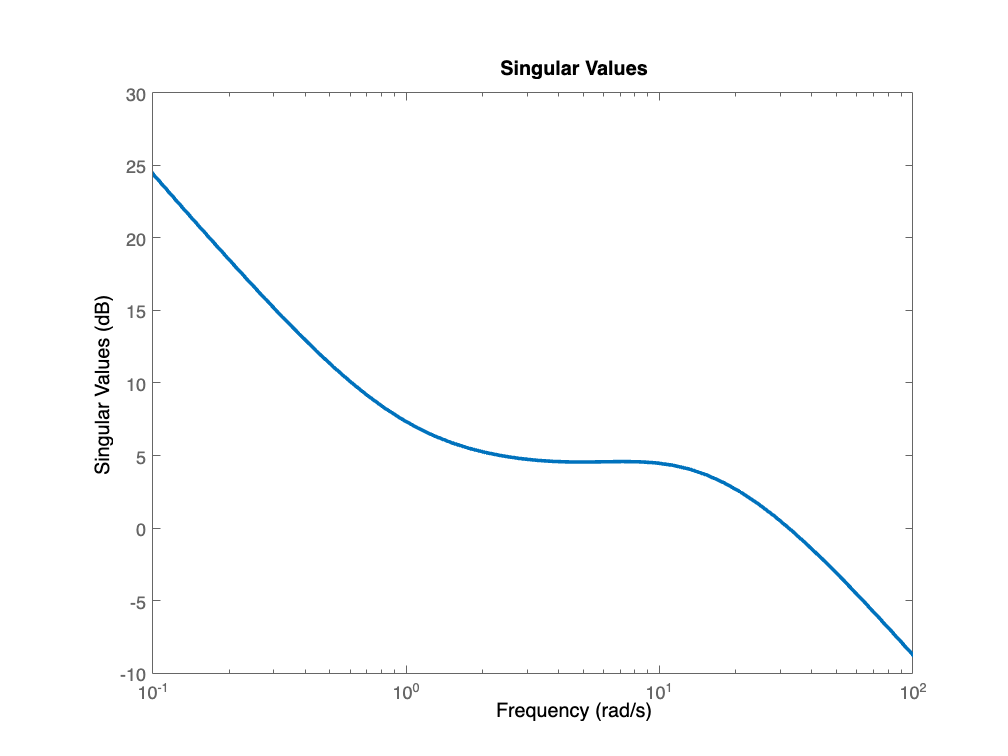

figure(2);
sigma(sys_ol); % this command is needed to plot singular values
set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

**TO-DO: **We must interpret this singular values plot in a meaningful way.

## Pole Placement Controller Design

We want first to design a pole placement controller able to stabilize the pendulum around the vertical position.

We'll assume that the full state is measurable.

% Compute the reachability matrix for the pair (A, B)
n = size(A,1); % order of the system 
m = size(B_u,2); % input dimension
p = size(C,1); % measured_output dimension

We check that the pair of the system we want to control is **reachable:**

M_r = ctrb(A, B_u); % this function computes the reachabiltiy matrix of the system
rank(M_r) == n % we compute the rank of Mr and compare it to the order of the system -> number of states

ans = logical
   1


### Chosing the poles positions

We stabilize the system and make it behave as a 2nd order system with a cutoff frequency of 5rad/s almost.

pp_desired_poles = [-5 -5.1 -15 -15.1];
Kpp = place(A, B_u, pp_desired_poles)

Kpp =    -5.0020   30.4519   -3.3066    4.4513


We then want to compare the singular values of the stabilized loop with the open loop ones:

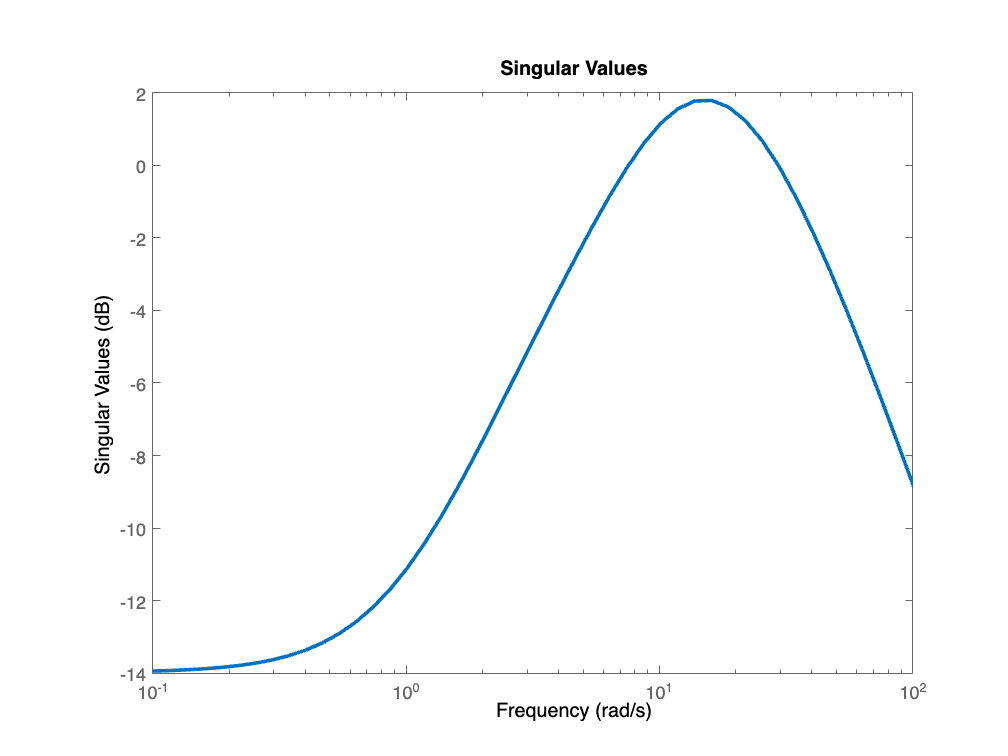

sys_cl_pp = ss(A - B_u * Kpp, B_u, C_full, D_full_u); % we define a ss representation

figure(3);
sigma(sys_cl_pp); % we compute eigs
set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

## Observer Design

In this section the design of a full order observer is performed.

First we verify that the system for which we want to design the observer is **observable**, aka that we have a sufficient number of sensors:

M_o = obsv(A, C);
rank(M_o) == n

ans = logical
   1


% obsv_poles = [-90,-90.1, -55+50i, -55-50i];
% obsv_poles = [-60,-60.1,-70,-70.1];
obsv_poles = [-40-4i,-40+4i,-50-5i,-50+5i];

Introducing complex conjugate poles allowed to reduce the inverse response of the observer.

L_obs = place(A', C', obsv_poles)'

L_obs = 1.0e+03 *

    0.0730   -0.0015
   -0.0158    0.0900
    0.8119   -0.0111
   -1.2200    2.0502


A_ob = A - L_obs*C;
B_ob = [B_u - L_obs*D, L_obs];
C_ob = eye(n);
D_ob = zeros(n, m+p);

% initial conditions for observer
x0_ob = [0;0;0;0];

% sys_obs = ss(A_ob,B_ob,C_ob,D_ob);
% obs_poles = pole(sys_obs)
% obs_zeros = tzero(sys_ol)
% figure(4);
% pzmap(sys_obs)
% set(findobj(gca, 'type', 'line'), 'MarkerSize', 12);
% figure(5);
% sigma(sys_obs); % we compute eigs
% set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

x0 = [0;0.26;0;0]; % initial state for simulation alpha range in +/- 0.26 rad (+/- 15°)
% x0 = [0;0.09;0;0]; % initial condition of 5°

## Performances through Integrators

### Full-State Controller Performances

In order to track a given reference we need to enlarge the system by introducing integrators. In particular we'll add a number of integrators equal to the number of output that we want to track.

We know that **the system to be controlled has no derivative action since there's no zero**. So we can effectively introduce integrators to achieve performances of the control system.

However we have that the number of output is greater than the number of inputs: $p>m$.

So we first need to consider the reduced order system and check if:

- $p\le m$ which is always verified when dealing with a scalar system

- there's no zero with derivative action: $s\not= 0\;$in $N\left(s\right)$.

### $G_{V\alpha \;} \left(s\right)$:

We compute the transfer function of the open loop system from the input to the alpha angle.

- $p=m$ is verified since the system is scalar

G_sys_ol = tf(sys_ol);

G_alpha = G_sys_ol(2)

G_alpha =
 
         25.42 s - 2.994e-15
  ---------------------------------
  s^3 + 17.04 s^2 - 40.89 s - 700.6
 
Continuous-time transfer function.



zero(G_alpha)

ans = 1.1776e-16

We can see **there's a zero very close to the origin**, this imply that we cannot control the alpha angle through our input.

### $G_{V\theta \;} \left(s\right)$:

Now we repeat for the transfer function from the voltage to the horizontal arm angle:

G_theta = G_sys_ol(1);
zero(G_theta)

ans =    -6.7456
    6.2884


We can see no zero is present in this transfer function, aka the state is controllable toward constant reference values.

### System Enlargement

The state space matrices of the enlarged system are:

pc = 1; % number of controllable outputs

A_tilde = [A zeros(n,pc);
           -C(1,:) zeros(pc)];
B_tilde = [B_u;
           zeros(pc)];
M_tilde = [zeros(n,pc);
           eye(pc)];

### Pole Placement Controller Design for the enlarged system

We need to decide where to place the poles for this system.

We can start by considering that we expect a fast dynamics associated to the stabilization of the pendulum and a slower dynamics associated to the control of the position of the horizontal arm.

We can look first at the natural frequency of the pendulum in the down position:

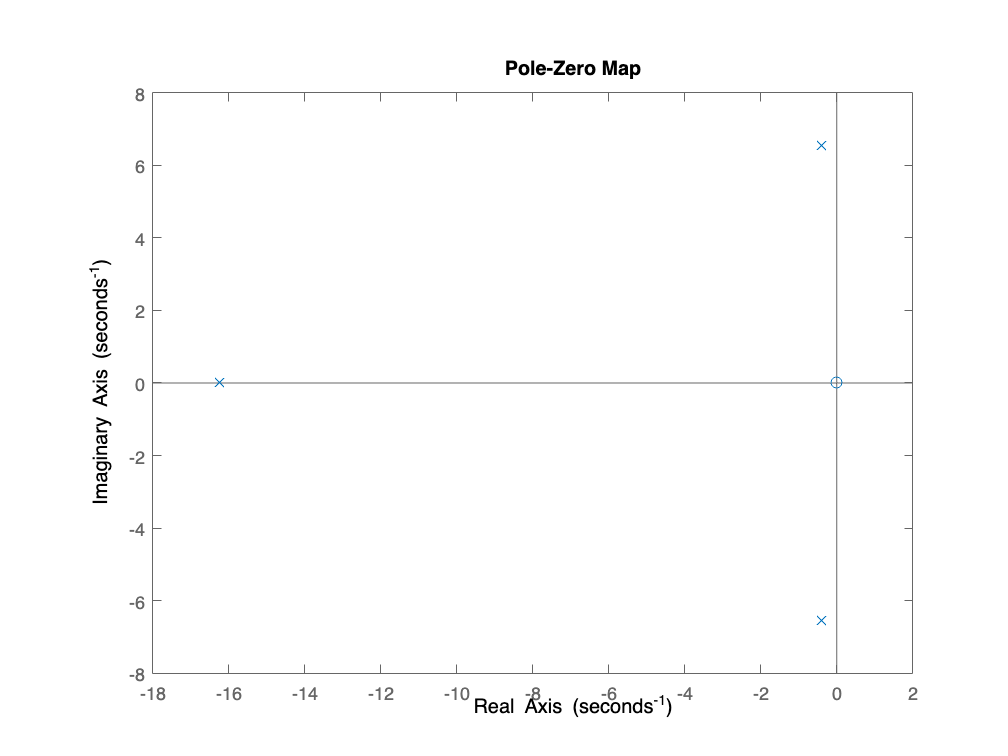

[A_down,B_down,C_down,D_down] = SS_Matrices_Voltage_Stable(B_p,B_r,J_T,J_a,J_p,K_g,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
C_down = eye(4); % full state feedback
D_down = zeros(4,1);

sys_down = ss(A_down,B_down,C_down,D_down);
tf_sys_down = tf(sys_down);
tf_sys_down_alpha = tf_sys_down(2);
pzmap(tf_sys_down_alpha)

From this map we can see that for the transfer function from the voltage to the alpha angle the doinant poles are a complex conjugate pair.

Now we proceed to compute the natural frequency and the damping ratio of these poles.

damp(tf_sys_down_alpha)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.96e-01 + 6.55e+00i     6.03e-02       6.57e+00         2.52e+00    
 -3.96e-01 - 6.55e+00i     6.03e-02       6.57e+00         2.52e+00    
 -1.62e+01                 1.00e+00       1.62e+01         6.16e-02    


We can see that the 2 c.c. poles have a natural frequency of $6\ldotp 57\;\frac{\textrm{rad}}{s}$. That's approximately the natural frequency of the pendulum.

We try to place 2 poles at $\lambda_{1,2} =-\zeta \;\omega {\;}_n \pm {j\omega }_n$. Choosing a $\zeta =0\ldotp 7\;$to reduce both the overshoot and have a fast rise time.

For the control of theta, we choose $\zeta =1$ to provide a zero overshoot and a natural frequency that allow to get a sufficiently fast rise time with respect to the unitary step

%en_desired_poles = [-3.3-6.57i -3.3+6.57i -1.54-2.2i  -1.54+2.2i, -20];

en_desired_poles = [-6-9i -6+9i -7 -7.001, -15]; % this one

% en_desired_poles = [-8.5-17i -8.5+17i -6.3+9i -6.3-9i, -20]; % not bad
% en_desired_poles = [-7.5-15i -7.5+15i -8 -8.1, -20]; % up to now the best one
% en_desired_poles = [-10.5-15i -10.5+15i -8 -8.1, -20];
% en_desired_poles = [-11.9-17i -11.9+17i -9 -9.1, -20];

We set randomly the poles of integrators, recalling that we never use pure integrators but first order systems !!!

Ken = place(A_tilde, B_tilde, en_desired_poles)

Ken =   -34.6883   71.6338   -9.0037   10.5825   74.4857


Then split the gain as $K_{\textrm{en}} =\left\lbrack \begin{array}{cc}
K_{\textrm{en},x}  & K_{\textrm{en},\eta \;} 
\end{array}\right\rbrack \;$such that $u=-K_{\textrm{en}} \;\tilde{x} =-K_{\textrm{en},x} \;\hat{x} -K_{\textrm{en},\eta \;} \eta \;$

Note that we don't need to redesign a state obserever since we can use the one previously designed.

Ken_x = Ken(:, 1:n); % control of original system states
Ken_eta = Ken(:, n+1:end); % control of integrators states